foldershg = '..//..//Data//registration_data//test_regsitration_20x20_1';
% save_folder = 'Registration2025-11-11//Run-1-tiffs';
filesshg = dir([foldershg '//*.tif']);
% filesshg = filesshg(3:end);
files_positions_shg = arrayfun(@(i) filesshg(i).name(35:47),1:length(filesshg),'UniformOutput',false);



pos_file_shg = '..//..//Data//registration_data//SHG_fiducial_markers_20x20_list.pos';
jsonText_shg = fileread(pos_file_shg);
datastruct_shg = jsondecode(jsonText_shg);
pos_struct_shg = datastruct_shg.map.StagePositions.array;
% pos_struct(1).Label.scalar
positions_shg = zeros(length(pos_struct_shg),2);
positions_shg_labels = cell(length(pos_struct_shg),1);
for i=1:(length(pos_struct_shg))
    positions_shg(i,:) = pos_struct_shg(i).DevicePositions.array.Position_um.array'/1000;
    positions_shg_labels{i} = pos_struct_shg(i).Label.scalar;
end
dx_shg = 262.4/256 /1000;
xs_shg = (0:255) * dx_shg

xs_shg =          0    0.0010    0.0020    0.0031    0.0041    0.0051    0.0061    0.0072    0.0082    0.0092    0.0102    0.0113    0.0123    0.0133    0.0143    0.0154    0.0164    0.0174    0.0184    0.0195    0.0205    0.0215    0.0225    0.0236    0.0246    0.0256    0.0266    0.0277    0.0287    0.0297    0.0307    0.0318    0.0328    0.0338    0.0348    0.0359    0.0369    0.0379    0.0389    0.0400    0.0410    0.0420    0.0430    0.0441    0.0451    0.0461    0.0471    0.0482    0.0492    0.0502


ys_shg = xs_shg;


tifdata = zeros(length(positions_shg_labels),256,256);
for i=1:length(filesshg)
    imageData = imread(fullfile(foldershg,filesshg(i).name));
    target_pos = files_positions_shg{i};
    for j=1:length(positions_shg_labels)
        if strcmp(target_pos,positions_shg_labels{j})
            tifdata(j,:,:) = imageData;
        end
    end
end

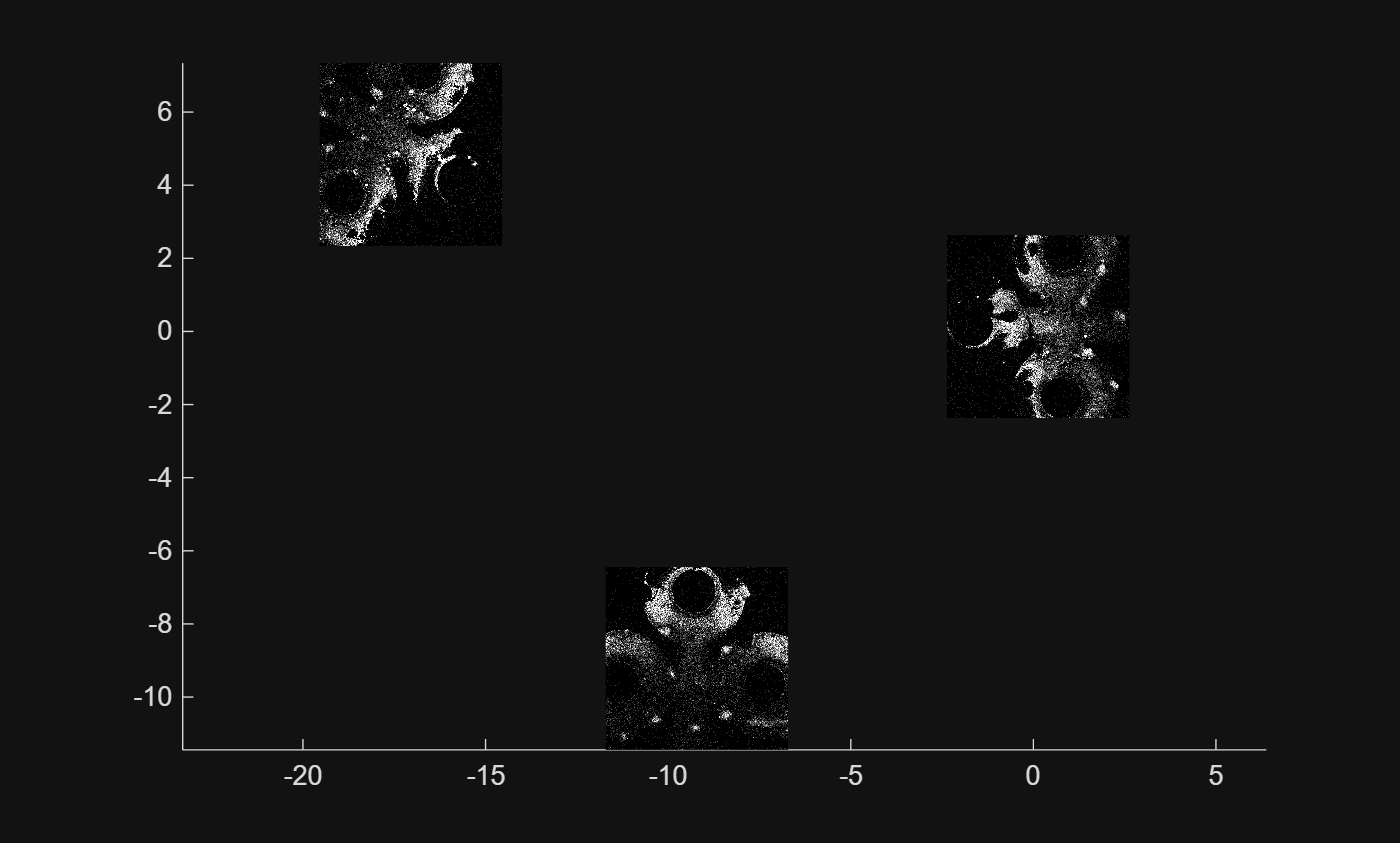

figure()
hold on
for i=1:length(positions_shg_labels)
    imagesc(xs_shg + positions_shg(i,1),ys_shg + positions_shg(i,2),squeeze(tifdata(i,:,:)),[0 5])
end
hold off
colormap gray
axis equal